%wczytanie koniecznych parametrów i wyliczenie wzocnień oraz punktów równowagi 
clear all
close all
run("wyliczanie_jacobianow_oraz_p_row.mlx")

ans = 0.0100

mwag_cal = -18.2574

close all
initial_x = 0.013;
%initial_x = 0.011;
max_x = 0.0212;
expected_z = 0.01;
KW = -[polyval(p_z,expected_z) polyval(p_v,expected_z) polyval(p_i,expected_z)];
Kw = -[polyval(p_z,expected_z)*max_x polyval(p_v,expected_z)*3/2 polyval(p_i,expected_z)*3];


GENERAL INFO

obsInfo = rlNumericSpec([3 1], LowerLimit=[-1 -1 -1]', UpperLimit=[ 1 1 1]');
actInfo = rlNumericSpec([1 1],"UpperLimit",-1,"LowerLimit",-1); 


obsInfo.Name = "observations";
obsInfo.Description = "position z, velocity v, current";
actInfo.Name = "control";

env = rlSimulinkEnv("MODEL_neural","MODEL_neural/controller",obsInfo,actInfo);
env.ResetFcn = @start;

Ts = 5e-3;
Tf = 0.5;
rng(0,"twister");

CRITIC

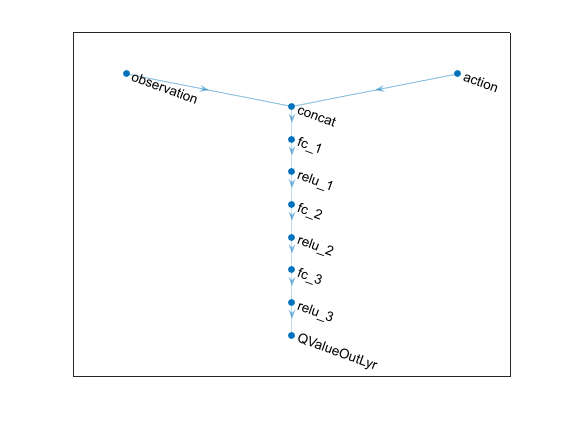

% Observation and action paths
% obsPath = featureInputLayer(3,Name="observation");
% actPath = featureInputLayer(1,Name="action");
% 
% % Common path
% commonPath = [
%     concatenationLayer(1,2,Name="concat")
%     quadraticLayer
%     fullyConnectedLayer(1,Name="value", ...
%         Bias=-0.5, Weights= [-1.1, -0.1, -1.1, -0.1, -0.1, -1.1 -0.1 -0.1 -0.1 -1.1 ])
%     ];
% 
% %BiasLearnRateFactor=0,
% criticNet = dlnetwork;
% criticNet = addLayers(criticNet,obsPath);
% criticNet = addLayers(criticNet,actPath);
% criticNet = addLayers(criticNet,commonPath);
% 
% criticNet = connectLayers(criticNet,"observation","concat/in1");
% criticNet = connectLayers(criticNet,"action","concat/in2");

observationPath = [
    featureInputLayer(3,Name="observation")
    concatenationLayer(1,2,Name="concat")
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(1,Name="QValueOutLyr")
    ];
actionPath = featureInputLayer(1,Name="action");


criticNet = dlnetwork;
criticNet = addLayers(criticNet, observationPath);
criticNet = addLayers(criticNet, actionPath);
criticNet = connectLayers(criticNet,"action","concat/in2");

plot(criticNet)

summary(initialize(criticNet))


   Initialized: true

   Number of learnables: 2.9k

   Inputs:
      1   'observation'   3 features
      2   'action'        1 features




% criticNet = initialize(criticNet);
% summary(criticNet)
critic = rlQValueFunction(criticNet, ...
    obsInfo,actInfo, ...
    ObservationInputNames="observation", ...
    ActionInputNames="action", ...
    UseDevice='gpu');


% commonPath = [
%     featureInputLayer(3,Name="observation")
%     fullyConnectedLayer(1 ,Bias=0,Name="commonPath", Weights=[6 8 -1],BiasLearnRateFactor=0)
%     ];
% 
% %commonPath(2).Weights=[4 6 0];
% %commonPath(2).Bias= 0
% 
% 
% meanPath = [
%    % fullyConnectedLayer(1,Name="meanFC")
%     reluLayer(Name="meanFC")
%     fullyConnectedLayer(1,Name="actionMean",Bias=0, Weights=[1],BiasLearnRateFactor=0, WeightLearnRateFactor=0)
%     ];
% stdPath = [
%     fullyConnectedLayer(1,Name="stdFC", Weights=[0.01],Bias=0,BiasLearnRateFactor=0.001, WeightLearnRateFactor=0.001)
%     reluLayer(Name="actionStd")
%     %reluLayer(Name="stdFC")
%     ];
% % ,BiasLearnRateFactor=0

commonPath = [
    featureInputLayer(3,Name="observation")
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer(Name="commonPath")
    ];
meanPath = [
    fullyConnectedLayer(16,Name="meanFC")
    reluLayer
    fullyConnectedLayer(1,Name="actionMean")
    ];
stdPath = [
    fullyConnectedLayer(1,Name="stdFC", WeightsInitializer="zeros", Bias=0.1)
    softplusLayer(Name="actionStd")
    ];

rng(0,"twister");
actorNet = dlnetwork;
actorNet = addLayers(actorNet,commonPath);
actorNet = addLayers(actorNet,meanPath);
actorNet = addLayers(actorNet,stdPath);
actorNet = connectLayers(actorNet,"commonPath","meanFC/in");
%actorNet = connectLayers(actorNet,"commonPath","actionMean/in");
actorNet = connectLayers(actorNet,"commonPath","stdFC/in");
summary(initialize(actorNet))


   Initialized: true

   Number of learnables: 2.9k

   Inputs:
      1   'observation'   3 features



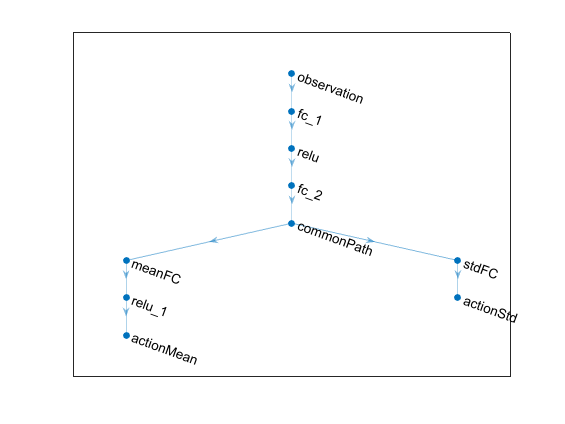

plot(actorNet)

actor = rlContinuousGaussianActor(actorNet, obsInfo, actInfo, ...
    ObservationInputNames="observation", ...
    ActionMeanOutputNames="actionMean", ...
    ActionStandardDeviationOutputNames="actionStd", ...
    UseDevice='gpu');

AGENT


agentOpts = rlSACAgentOptions( ...
    SampleTime             = Ts, ...
    ExperienceBufferLength = 1e4, ...
    NumWarmStartSteps      = 128, ...
    MiniBatchSize          = 128, ...
    DiscountFactor         = 0.95, ...
    PolicyUpdateFrequency  = 1, ...
    TargetUpdateFrequency  = 1, ...
    NumStepsToLookAhead    = 1  ...
    );

agentOpts.ActorOptimizerOptions.Algorithm = "adam";
agentOpts.ActorOptimizerOptions.LearnRate = 5e-4;
agentOpts.ActorOptimizerOptions.GradientThreshold = 100;

%agentOpts.ActorOptimizerOptions.OptimizerParameters

agentOpts.CriticOptimizerOptions(1).Algorithm = "adam";
agentOpts.CriticOptimizerOptions(1).LearnRate = 5e-3;
agentOpts.CriticOptimizerOptions(1).GradientThreshold = 100;

% agentOpts.CriticOptimizerOptions(2).Algorithm = "adam";
% agentOpts.CriticOptimizerOptions(2).LearnRate = 1e-3;
% agentOpts.CriticOptimizerOptions(2).GradientThreshold = 10;

agentOpts.EntropyWeightOptions.EntropyWeight = 5e-3;
% agentOpts.EntropyWeightOptions.LearnRate = 1e-3;
% agentOpts.EntropyWeightOptions.GradientThreshold = 1;


agent = rlSACAgent(actor,critic,agentOpts);

% training options
trainOpts = rlTrainingOptions(...
    MaxEpisodes=2000, ...
    MaxStepsPerEpisode=floor(Tf/Ts), ...
    ScoreAveragingWindowLength=100, ...
    StopTrainingCriteria= "none" , ...
    SimulationStorageType="none");

evl = rlEvaluator(EvaluationFrequency=25, NumEpisodes=5);
%    StopTrainingValue = -9.9*20, ...
doTraining = 1;

if doTraining
    trainingStats = train(agent,env,trainOpts,Evaluator=evl);
    save("SAC_aget_64_szum","agent")
end